## Concept Check: Introduction to Motion Detection

Q1. Background - stable background / Feature matching - detected object / template - manually / optical - two subsequent

Q2. Feature

Q3. Away

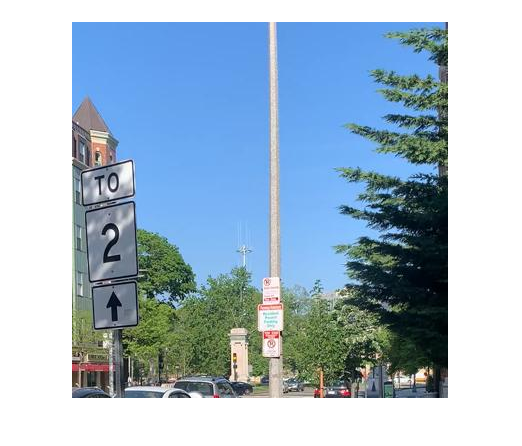

shakyV = VideoReader("ShakyStreet.avi");
stableV = VideoWriter("simpleStabilizedVideo.avi");
frame1 = read(shakyV,1);
imshow(frame1)

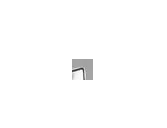

% imtool(frame1)
templateOrigin = [60,140];
wt = 20;
ht = 20;
xmin = templateOrigin(1) - round(wt/2);
ymin = templateOrigin(2) - round(ht/2);
template = imcrop(frame1,[xmin,ymin,wt,ht]);
template = im2gray(template);
imshow(template)

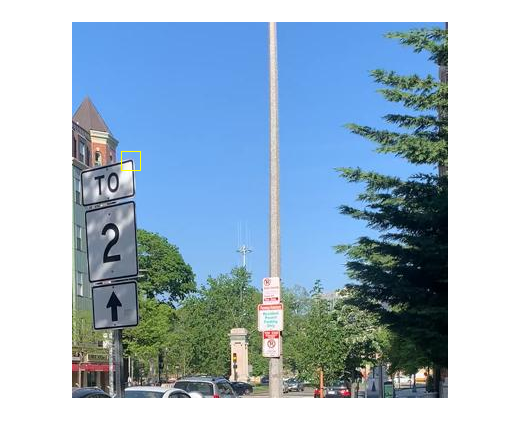

frame1 = insertShape(frame1,"rectangle",[xmin,ymin,wt,ht]);
imshow(frame1)


xMinOffset = 0;
xMaxOffset = 0;
yMinOffset = 0;
yMaxOffset = 0;

templateMatcher = vision.TemplateMatcher();
open(stableV)

nFrames = shakyV.NumFrames;
for ii = 1:nFrames
    currFrameColor = read(shakyV,ii);
    currFrameGray = im2gray(currFrameColor);
    currFrameGray = im2double(currFrameGray);
    template = im2double(template);
    templatePos = templateMatcher(currFrameGray,template);
    offset = double(templatePos) - templateOrigin;
    stabilizedFrame = imtranslate(currFrameColor,-offset);
    writeVideo(stableV,stabilizedFrame);
    if offset(1) < xMinOffset
        xMinOffset = offset(1);
    end
    if offset(1) > xMaxOffset
        xMaxOffset = offset(1);
    end
    if offset(2) < yMinOffset
        yMinOffset = offset(2);
    end
    if offset(2) > yMaxOffset
        yMaxOffset = offset(2);
    end
end
close(stableV)

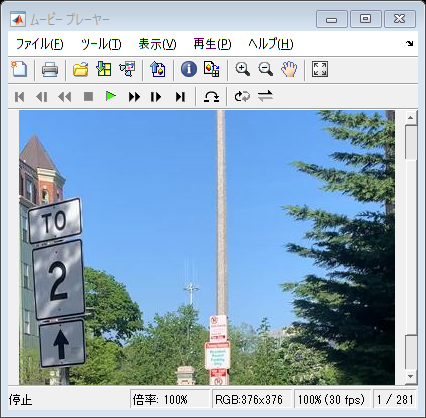

nrows = size(frame1,1);
ncols = size(frame1,2);
rowIndices = abs(yMinOffset) + 1:nrows - yMaxOffset;
colIndices = abs(xMinOffset) + 1:ncols - xMaxOffset;

newV = VideoReader("simpleStabilizedVideo.avi");
vCropped = VideoWriter("simpleStabilizedVideoCropped.avi");
open(vCropped)
nFrames = newV.NumFrames;

for jj = 1:nFrames
    frame = read(newV,jj);
    frame = frame(rowIndices,colIndices,:);
    writeVideo(vCropped,frame);
end
close(vCropped)

implay("ShakyStreet.avi")
figure
implay("simpleStabilizedVideo.avi")

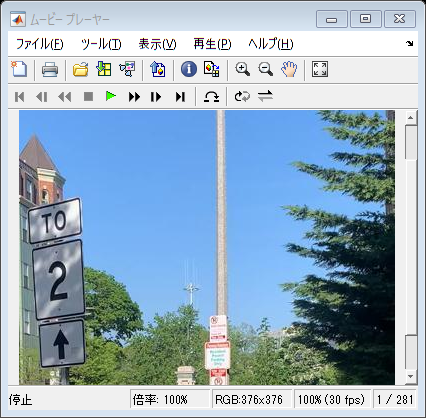

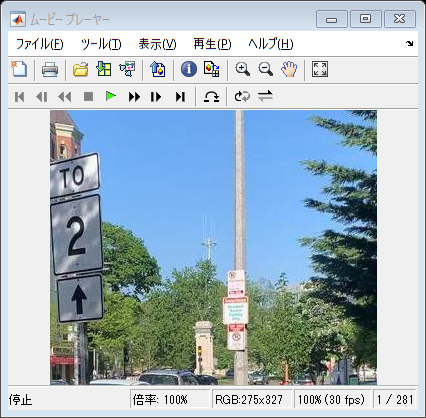

figure
implay("simpleStabilizedVideoCropped.avi")

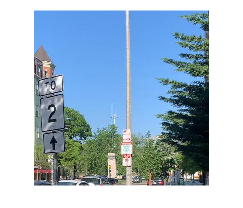

shakyV = VideoReader("ShakyStreet.avi");
stableV = VideoWriter("robustStabilizedVideo.avi");
frame1 = read(shakyV,1);
imshow(frame1)

templateOrigin = [60 140];
wT = 20;
hT = 20;
xmin = templateOrigin(1) - round(wT/2);
ymin = templateOrigin(2) - round(hT/2);
template = imcrop(frame1,[xmin ymin wT hT]);
template = im2gray(template);
wROI = 50;
hROI = 50;
xminROI = templateOrigin(1) - round(wROI/2);
yminROI = templateOrigin(2) - round(hROI/2);
searchROI = [xminROI yminROI wROI hROI];
imshow(template)

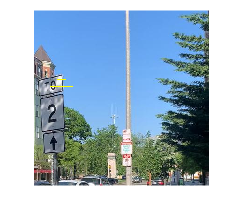

frame1 = insertShape(frame1,"rectangle",[xmin ymin wT hT]);
frame1 = insertShape(frame1,"rectangle",[xminROI yminROI wROI hROI]);
imshow(frame1)

xMinOffset = 0;
xMaxOffset = 0;
yMinOffset = 0;
yMaxOffset = 0;
templateMatcher = vision.TemplateMatcher("ROIInputPort",true);

offset = [0 0];
prevTemplatePos = templateOrigin;

open(stableV)
nFrames = shakyV.NumFrames;
for ii = 1:nFrames
    currFrameColor = read(shakyV,ii);
    currFrameGray = im2gray(currFrameColor);
    currFrameGray = im2double(currFrameGray);
    template = im2double(template);
    templatePos = templateMatcher(currFrameGray,template,searchROI);

    templatePos = double(templatePos);
    displacement = templatePos - templateOrigin;
    offset = offset + displacement;
    stabilizedFrame = imtranslate(currFrameColor,-offset);
    writeVideo(stableV,stabilizedFrame);

    templateOrigin = templatePos;
    xmin = templateOrigin(1) - round(wT/2);
    ymin = templateOrigin(2) - round(hT/2);
    template = imcrop(currFrameGray,[xmin,ymin,wT,hT]);

    searchROIOrigin = templateOrigin;
    xminROI = templateOrigin(1) - round(wROI/2);
    yminROI = templateOrigin(2) - round(hROI/2);
    searchROI = [xminROI,yminROI,wROI,hROI];

    if offset(1) < xMinOffset
        xMinOffset = offset(1);
    end
    if offset(1) > xMaxOffset
        xMaxOffset = offset(1);
    end
    if offset(2) < yMinOffset
        yMinOffset = offset(2);
    end
    if offset(2) > yMaxOffset
        yMaxOffset = offset(2);
    end
end
close(stableV)

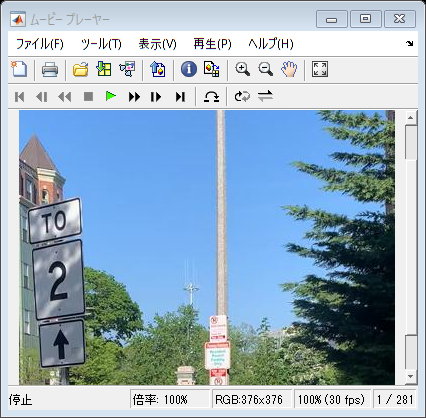

nrows = size(frame1,1);
ncols = size(frame1,2);
rowIndices = abs(yMinOffset)+1:nrows-yMaxOffset;
colIndices = abs(xMinOffset)+1:ncols-xMaxOffset;

newV = VideoReader("robustStabilizedVideo.avi");
vCropped = VideoWriter("robustStabilizedVideoCropped.avi");
open(vCropped)
nFrames = newV.NumFrames;

for jj = 1:nFrames
    frame = read(newV,jj);
    frame = frame(rowIndices,colIndices,:);
    writeVideo(vCropped,frame);
end

close(vCropped)

implay("ShakyStreet.avi")
figure
implay("robustStabilizedVideo.avi")

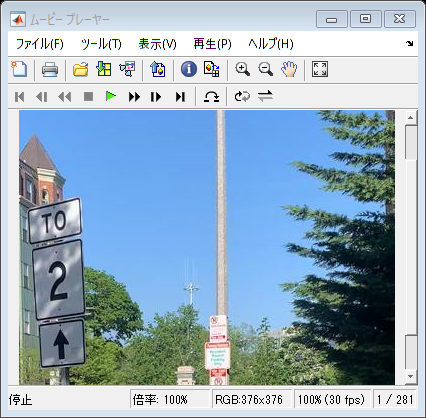

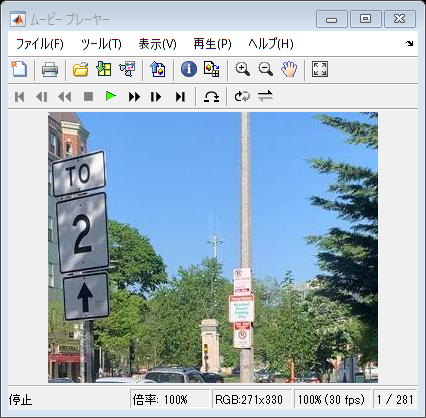

figure
implay("robustStabilizedVideoCropped.avi")

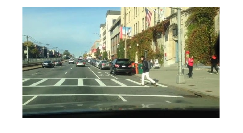

myVideoReader = VideoReader("pedtracking.mp4");
myVideoWriter = VideoWriter("pedtracking_motion.avi");
myOpticalFlow = opticalFlowFarneback;

startFrame = 96;
endFrame = 565;

frame = read(myVideoReader,startFrame);
imshow(frame)

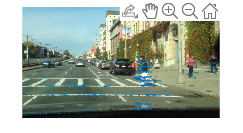

estimateFlow(myOpticalFlow,im2gray(frame));

frame = read(myVideoReader,startFrame+1);
flow = estimateFlow(myOpticalFlow,im2gray(frame));

imshow(frame)
hold on
plot(flow,"DecimationFactor",[15 15],"ScaleFactor",7)
hold off

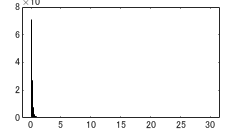

Vm = flow.Magnitude;
histogram(Vm)

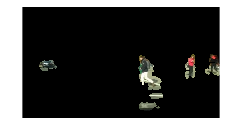

maskThreshold = 0.5;
mask = (Vm > maskThreshold);
maskedFrame = frame;
se = strel("disk",3,0);
mask = imopen(mask,se);
mask = bwareafilt(mask,[500,Inf]);
maskedFrame(repmat(~mask,[1,1,3])) = 0;
imshow(maskedFrame)

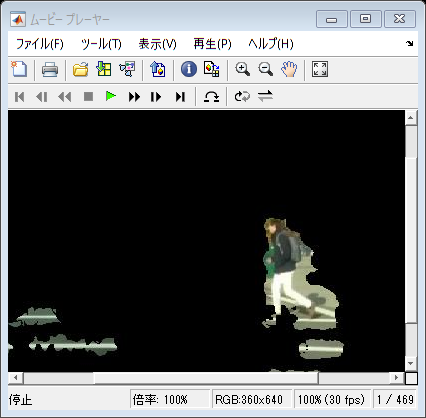

frame = read(myVideoReader,startFrame);
estimateFlow(myOpticalFlow,im2gray(frame));
open(myVideoWriter)
for ii = startFrame+1:endFrame
    frame = read(myVideoReader,ii);
    flow = estimateFlow(myOpticalFlow,im2gray(frame));
    maskThreshold = 0.5;
    mask = (flow.Magnitude > maskThreshold);
    mask = bwareafilt(mask,[500 Inf]);
    maskedFrame = frame;
    maskedFrame(repmat(~mask,[1,1,3])) = 0;
    writeVideo(myVideoWriter,maskedFrame);
end
close(myVideoWriter)
implay("pedtracking_motion.avi")

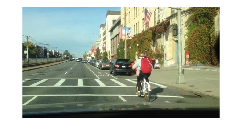

vid = VideoReader("pedtracking.mp4");
of = opticalFlowFarneback;

testFrameIdx = 349;
testFrame = read(vid,testFrameIdx);
imshow(testFrame)

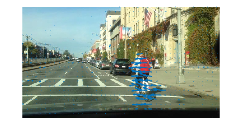

estimateFlow(of,im2gray(testFrame));
testFrame = read(vid,testFrameIdx+1);
testFlow = estimateFlow(of,im2gray(testFrame));
imshow(testFrame)
hold on
plot(testFlow,"DecimationFactor",[15 15],"ScaleFactor",7)
hold off

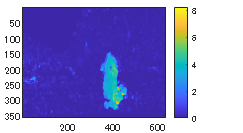

imagesc(testFlow.Magnitude)
colorbar

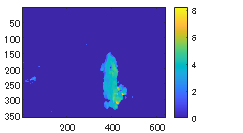

magThresh = 1;
threshFlow = testFlow.Magnitude >= magThresh;
maskedVm = testFlow.Magnitude;
maskedVm(~threshFlow) = 0;
imagesc(maskedVm)
colorbar

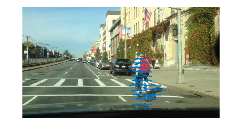

VxThresh = testFlow.Vx;
VxThresh(~threshFlow) = 0;
VyThresh = testFlow.Vy;
VyThresh(~threshFlow) = 0;
magThreshFlow = opticalFlow(VxThresh,VyThresh);
imshow(testFrame);
hold on
plot(magThreshFlow,"DecimationFactor",[15 15],"ScaleFactor",7)
hold off

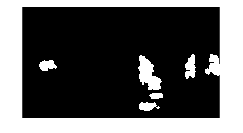

vidOut = VideoWriter("pedtracking_avgMag.mp4","MPEG-4");
startFrame = 96;
endFrame = 565;
of = opticalFlowFarneback;
frame = read(vid,startFrame);
estimateFlow(of,im2gray(frame));

frame = read(vid,startFrame+1);
flow = estimateFlow(of,im2gray(frame));
magThresh = 0.5;
mask = (flow.Magnitude > magThresh);
se = strel("disk",3,0);
mask = imopen(mask,se);
mask = bwareafilt(mask,[500 Inf]);
imshow(mask)

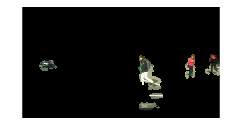

maskedFrame = frame;
maskedFrame(repmat(~mask,[1,1,3])) = 0;
imshow(maskedFrame)

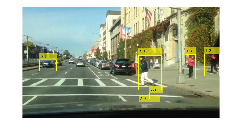

movObjs = regionprops("table",mask,flow.Magnitude,["MeanIntensity","BoundingBox"]);
if ~isempty(movObjs)
    labelFrame = insertObjectAnnotation(frame,"rectangle",movObjs.BoundingBox,string(round(movObjs.MeanIntensity,1)));
end
imshow(labelFrame)


open(vidOut)
writeVideo(vidOut,labelFrame)
close(vidOut)

magThresh = 0.5;
frame = read(vid,startFrame);
estimateFlow(of,im2gray(frame));
open(vidOut)
for ii = startFrame+1:endFrame
    frame = read(vid,ii);
    flow = estimateFlow(of,im2gray(frame));
    mask = (flow.Magnitude > magThresh);

    se = strel("disk",3,0);
    mask = imopen(mask,se);
    mask = bwareafilt(mask,[500 Inf]);

    movObjs = regionprops("table",mask,flow.Magnitude,"MeanIntensity","BoundingBox");
    if ~isempty(movObjs)
        labelFrame = insertObjectAnnotation(frame,"rectangle",movObjs.BoundingBox,string(round(movObjs.MeanIntensity)));
    end
    writeVideo(vidOut,labelFrame)
end
close(vidOut)

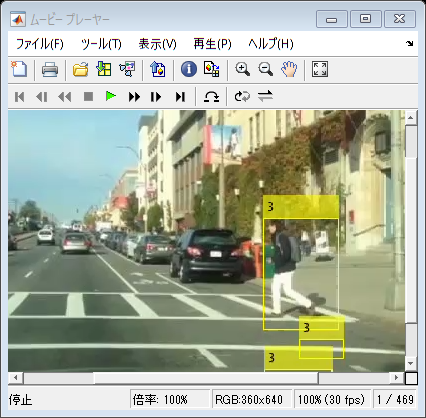

implay("pedtracking_avgMag.mp4")

## Graded Quiz: Detecting Motion

Q1. B

Q2. line 5

Q3. 0.6327

vidShaky = VideoReader("ShakyStreet.avi");
vidStabilized = VideoReader("simpleStabilizedVideoCropped.avi");

iFrame = 55;
frame = read(vidShaky,iFrame);
of = opticalFlowFarneback;
estimateFlow(of,im2gray(frame));
frame = read(vidShaky,iFrame+1);
flow = estimateFlow(of,im2gray(frame));
mean(flow.Magnitude(:))

ans = single
0.6327

Q4. 0.3806

frame = read(vidStabilized,iFrame);
of = opticalFlowFarneback;
estimateFlow(of,im2gray(frame));
frame = read(vidStabilized,iFrame+1);
flow = estimateFlow(of,im2gray(frame));
mean(flow.Magnitude(:))

ans = single
0.3806

## Project: Introduction to Applying Optical Flow to Determine the Direction of Traffic

frame1 = imread("Rt9Frame1.png");
frame2 = imread("Rt9Frame2.png");

of = opticalFlowFarneback;
estimateFlow(of,im2gray(frame1));
flow = estimateFlow(of,im2gray(frame2));
% imagesc(flow.Magnitude);
% colorbar;
magThresh = 1;
mask = (flow.Magnitude > magThresh);
% imshow(mask)
mask = bwareafilt(mask,[500 Inf]);
% imshow(mask)
se = strel("disk",20,0);
mask = imclose(mask,se);

% % Uncomment below to view your optical flow vectors on your masked image
% maskedFrame = frame2; maskedFrame(repmat(~mask, [1 1 3])) = 0;
% imshow(frame2)
% hold on
% plot(flow,"DecimationFactor",[15 15],"ScaleFactor",7)
% hold off
% figure
% imshow(maskedFrame)

movObjs = regionprops("table",mask,flow.Vx,"MeanIntensity");
leftVx = movObjs.MeanIntensity(movObjs.MeanIntensity < -3);
rightVx = movObjs.MeanIntensity(movObjs.MeanIntensity > 3);
numCarsLeft = numel(leftVx);
numCarsRight = numel(rightVx);